# Bogolyubov’s averaging theorem applied to the Kramers-Henneberger Hamiltonian

We compare the Cauchy problems starting at $(x,p)=(x_0,p_0)$ for the dynamics generated by the two Hamiltonians


$$H(x,p,t)=\frac{p^2}{2}-\frac{1}{\sqrt{(x+q\cos\omega t)^2+a^2}},$$



$$\overline{H}(x,p)=\frac{p^2}{2}-\frac{1}{2\pi}\int_0^{2\pi} \frac{1}{\sqrt{(x+q\cos\phi)^2+a^2}} {\rm d}\phi,$$


where $q=\frac{E_0}{\omega^2}$ and $E_{\rm KH}=\overline{H}(x_0,p_0) <0$. We estimate the differences $\sigma_x$(red line) and $\sigma_p$(dash-dotted line) given by


$$\sigma_x = \max_{t\leq t_{\rm max}} \vert x(t)-\overline{x}(t)\vert / q, \\
\sigma_p = \max_{t\leq t_{\rm max}} \vert p(t)-\overline{p}(t)\vert /(E_0/\omega).$$


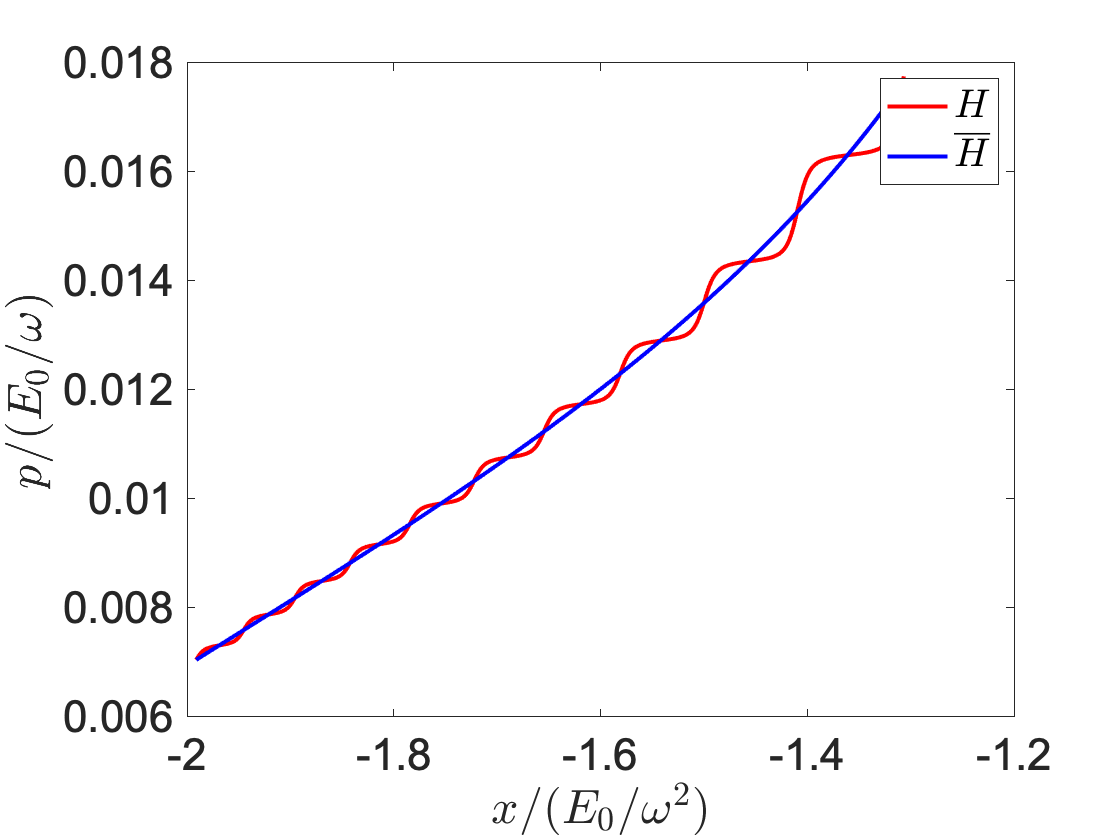

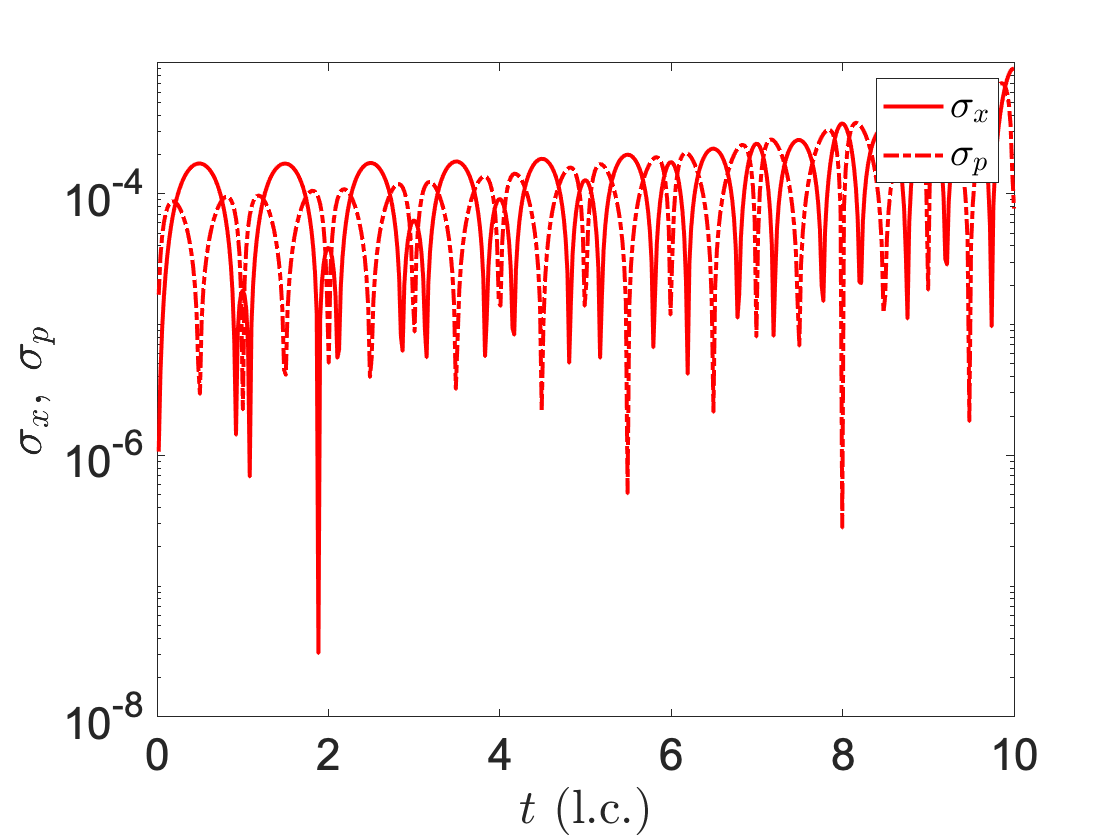

I = 5e15;
omega = 0.0584;
a = 1;
ncycle = 10;

h = 1e-8;
N = 500;

E0 = sqrt(I/3.5e16);
q_scale = E0/omega^2;
p_scale = E0/omega;
T = 2*pi/omega;
options = odeset('AbsTol', h, 'RelTol', h);
tspan = linspace(0, ncycle*T, N);
xv = linspace(0, 2*q_scale, N);
EKHmin = -max(integral(@(phi) 1./sqrt((xv+q_scale*cos(phi)).^2+a^2), 0, 2*pi, 'ArrayValued', true)/(2*pi));

x =-1.9911* q_scale;
EKH =-0.0042;
p = sqrt(2*(EKH+integral(@(phi) 1./sqrt((x+q_scale*cos(phi)).^2+a^2), 0, 2*pi)/(2*pi)));

if imag(p)==0
    
    [~, z] = ode45(@(t,y) [y(2); -(y(1)+q_scale*cos(omega*t))./((y(1)+q_scale*cos(omega*t)).^2+a^2).^1.5], tspan, [x, p], options);
    [~, zb] = ode45(@(t,y) [y(2); -integral(@(phi) (y(1)+q_scale*cos(phi))./((y(1)+q_scale*cos(phi)).^2+a^2).^1.5, 0, 2*pi)/(2*pi)], tspan, [x, p], options);
    
    figure(1), clf;
    plot(z(:,1)/q_scale, z(:,2)/p_scale, 'r', 'LineWidth', 2);
    hold(gca, 'on')
    plot(zb(:,1)/q_scale, zb(:,2)/p_scale, 'b', 'LineWidth', 2);
    xlabel('$x/(E_0/\omega^2)$', 'Interpreter', 'latex', 'FontSize', 25);
    ylabel('$p/(E_0/\omega)$', 'Interpreter', 'latex', 'FontSize', 25);
    set(gca, 'FontSize', 22, 'FontName', 'Arial', 'Box', 'on')
    legend('$H$', '$\overline{H}$', 'Interpreter', 'latex')
    
    figure(2), clf;
    semilogy(tspan/T, abs(z(:,1)-zb(:,1))/q_scale, 'r-', 'LineWidth', 2);
    hold(gca, 'on')
    semilogy(tspan/T, abs(z(:,2)-zb(:,2))/p_scale, 'r-.', 'LineWidth', 2);
    xlabel('$t$ (l.c.)', 'Interpreter', 'latex', 'FontSize', 25);
    ylabel('$\sigma_x, \; \sigma_p$', 'Interpreter', 'latex', 'FontSize', 25);
    set(gca, 'FontSize', 22, 'FontName', 'Arial', 'Box', 'on')
    xlim([0 ncycle])
    legend('$\sigma_x$', '$\sigma_p$', 'Interpreter', 'latex')
end